# Solution to the *Clustering Human Activity *exercise

## 1. Load data

Load the data in `HAData.mat`.

load HAData

This file contains a table, data, with 44 columns, containing sensor information for experimental participants performing 6 different activities. The second column, `Activity`, contains a label for the activity being performed. 

## 2. Extract data

Extract the sensor data (exclude the first two columns) from the table into a new variable, `measurements`.

measurements = data{:,3:end};

## 3. Do *k*-means clustering

Use *k*-means clustering to cluster the numeric data in measurements into four groups.

k = 4;

Set random seed for reproducibility.

rng(1234)
grp = kmeans(measurements,k);

## Create silhouette plot

Randomly select a subset of data to create a smaller set of the data for steps 4-6.

[meassub,idx] = datasample(measurements,2000);

Create a silhouette plot to evaluate the clustering. 

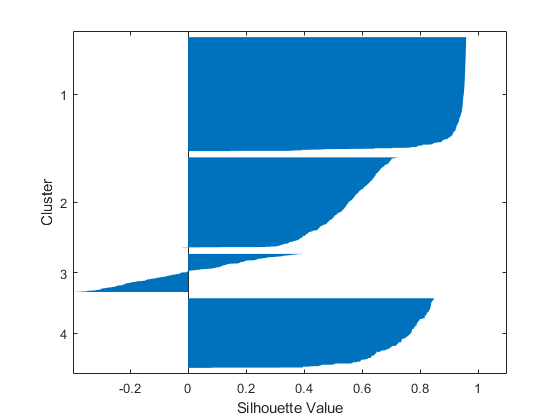

figure
silhouette(meassub,grp(idx))

## 4. Determine optimal number of clusters

Determine the optimal number of clusters by using the silhouette value.

clustev = evalclusters(meassub,'kmeans','silhouette','kList',2:6)

clustev =   SilhouetteEvaluation with properties:

    NumObservations: 2000
         InspectedK: [2 3 4 5 6]
    CriterionValues: [0.6457 0.7478 0.6540 0.6217 0.5978]
           OptimalK: 3


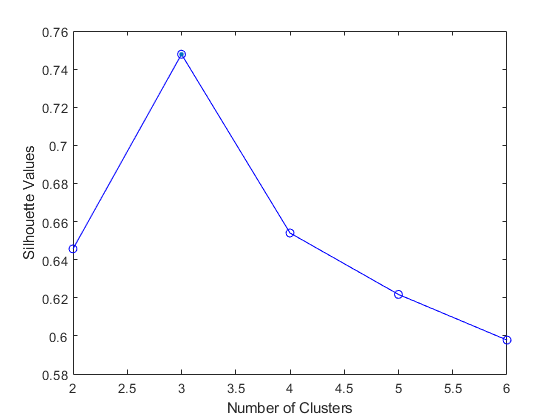

figure
plot(clustev)

## 5. Update clusters and silhouette plot

Use *k*-means to cluster to the optimal number of clusters.

k = 3;
grp = kmeans(measurements,k);

Create a silhouette plot to evalute the new clustering.

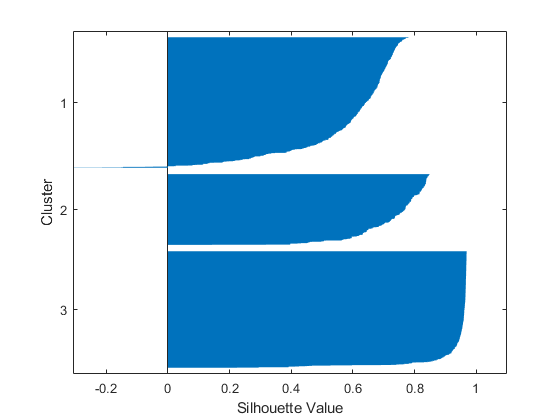

figure
silhouette(meassub,grp(idx))

## 6. Compare groups to activity categories

Compare the resulting clusters with the groups in the `Activity` variable using `crosstab`.  

c = crosstab(grp,data.Activity)

c =          807         717         579           1           0           1
           0           0           0          15           0        1116
           1           0           0         934        1079           0


## 7. Visualize results

Visualize the clustering results in a bar chart.

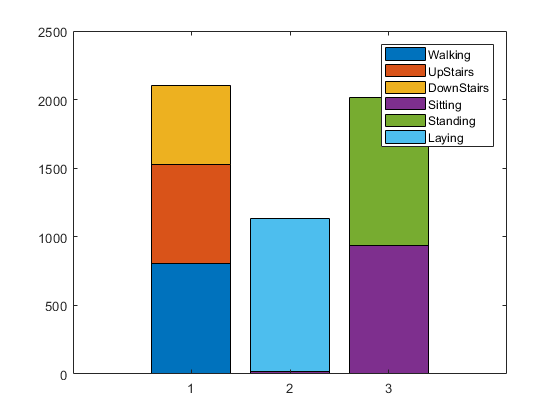

figure
bar(c,'stacked')
legend(categories(data.Activity))

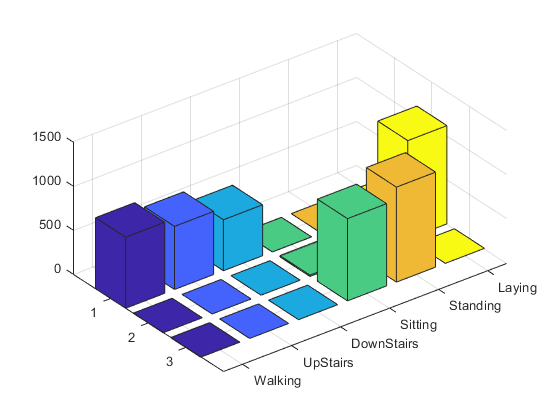


figure
bar3(c)
ax = gca;
ax.XTick = 1:6;
ax.XTickLabel = categories(data.Activity);